# Confidence Regions Tutorial

To run this tutorial you first need to add all functions in the StatBrainz toolbox to the matlab path. To do so you can navigate to the StatBainz folder and fun the function addSB2path.m. Alternatively you can fill in the directory and run the code below.

statsbrainz_directory_pathloc = 'C:\Users\jiyue\OneDrive - UC San Diego\Matlab_projects\StatBrainz';
addpath(genpath(statsbrainz_directory_pathloc));

## Surface cope sets

sb_dir = statbrainz_maindir;
% what are these surface images for?
% hcp_srf includes the topology info of the surface
path4gifti_L = [sb_dir, '\BrainImages\Gifti_files\S1200.L.inflated_MSMAll.32k_fs_LR.surf.gii'];
path4gifti_R = [sb_dir, '\BrainImages\Gifti_files\S1200.R.inflated_MSMAll.32k_fs_LR.surf.gii'];
hcp_srf = gifti2surf(path4gifti_L, path4gifti_R);
%this creates hcp_data_std and hcp_data_mean, each has two vectors for the lh and rh 
load([sb_dir,'BrainImages\Real_data\hcpWM_surface.mat'])

#### Generate data

FWHM = 10;
nsubj = 50,

nsubj = 50

% generates surface noise data with the surface structure 
X = srf_noise(hcp_srf.lh, FWHM, nsubj);

50 x 1 surfaces to smooth, % remaining: 100 90 80 70 60 50 40 30 20 10 0 Done


%./ and .* perfroms element-wise division and multiplication
% X(:) reshapes X into a column vector
% X is a matrix of shape 32492*50, contrast maps from 50 individuals
X = X./std(X(:));
X = X.*hcp_data_std.lh;
X = X + hcp_data_mean.lh;
size(X)

ans =        32492          50


## FDR cope sets

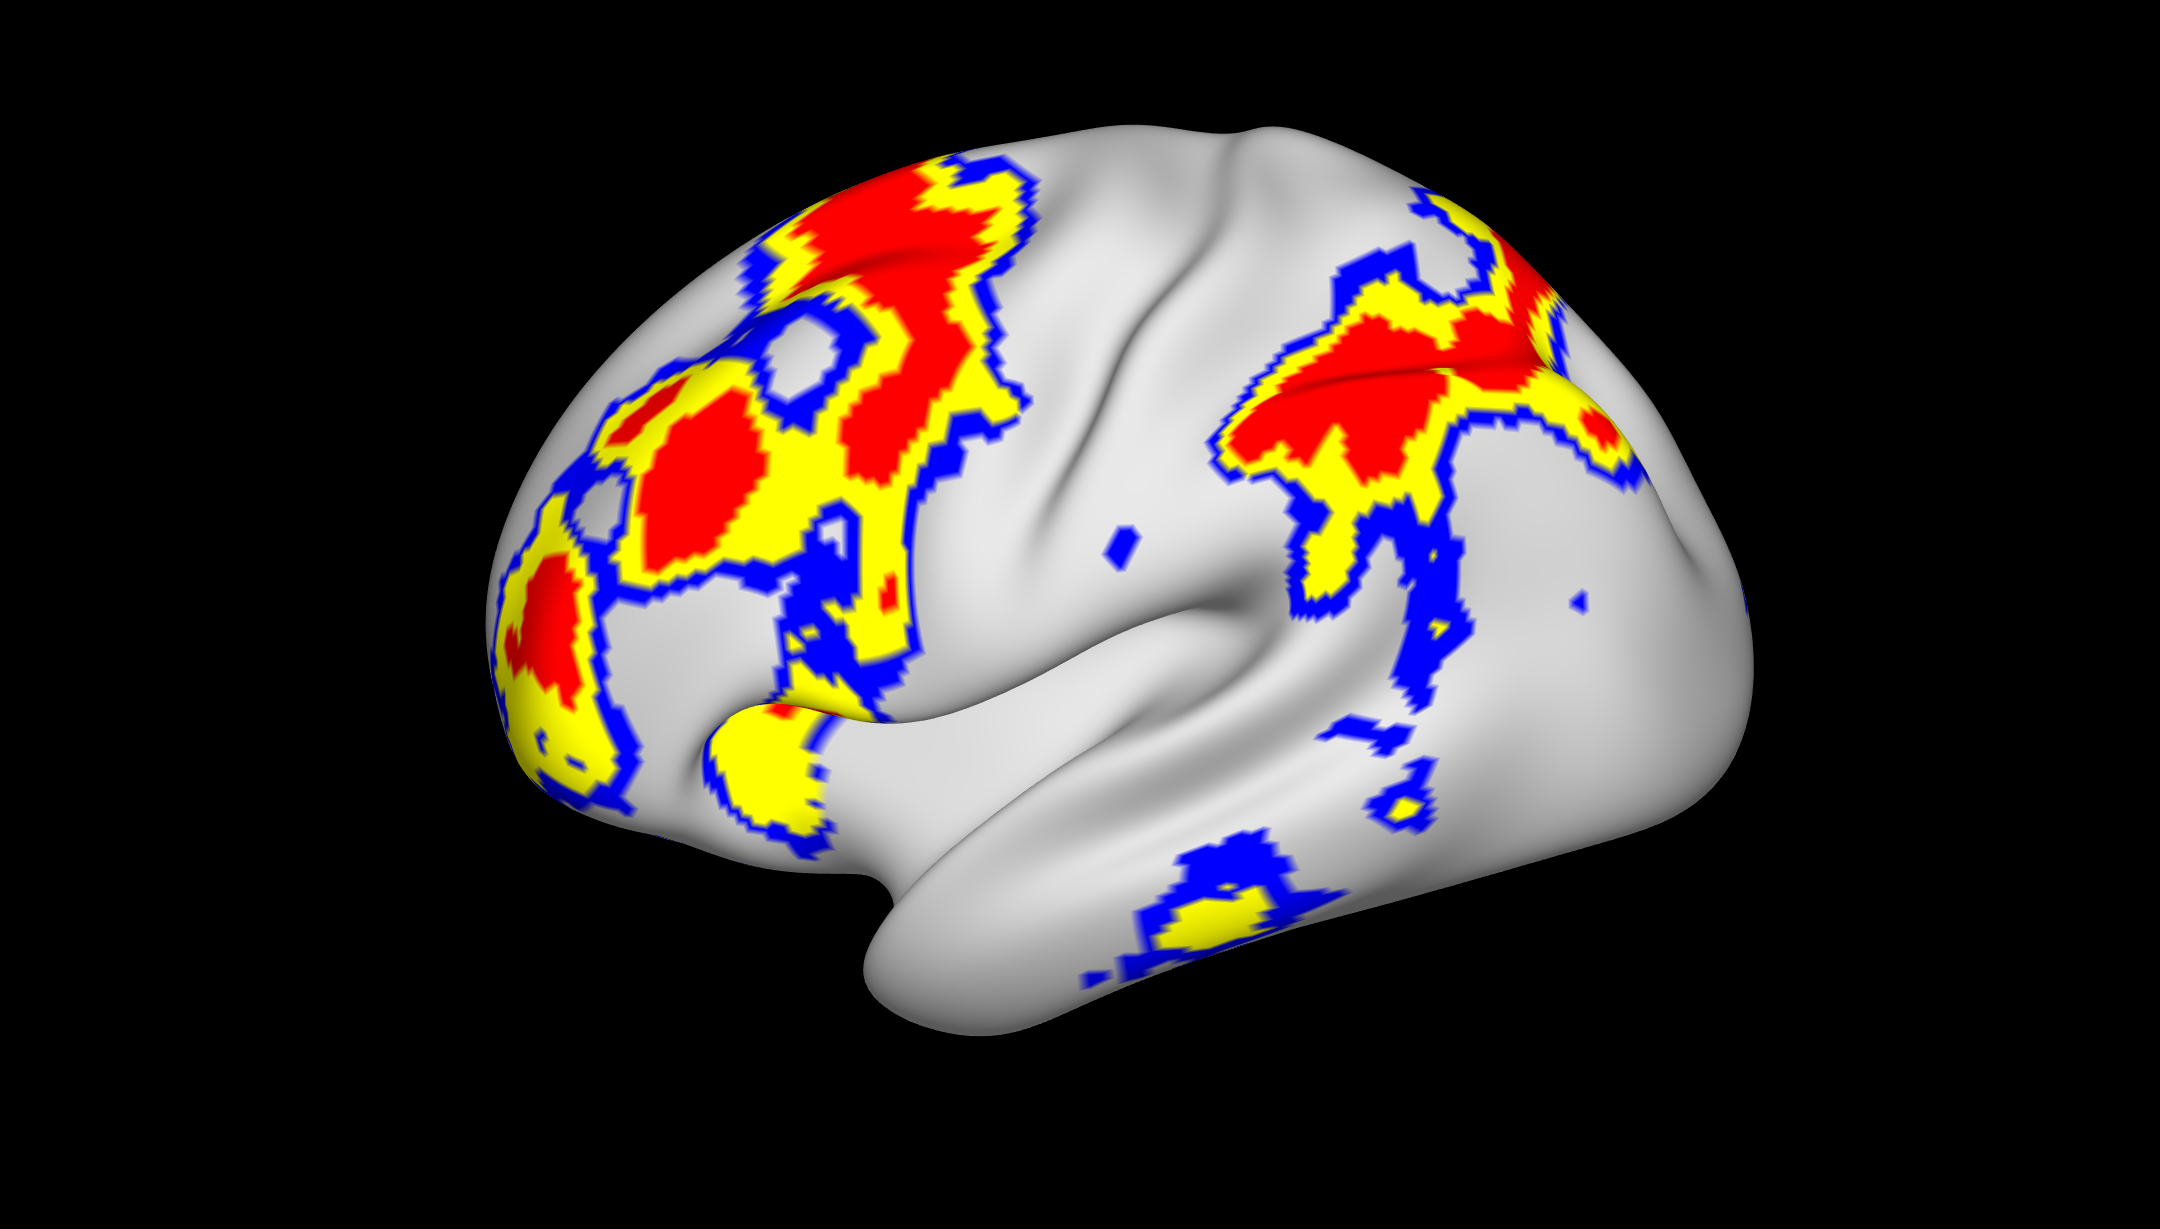

figure; set(gcf,'Visible','on')
c = 1;
% size(tstats)=32492*1 
[tstats, xbar] = mvtstat(X - c);
% tstat2pval( tstat, df, do2sample): here, degree of freedom is 50-1=49
pvals = tstat2pval(nan2zero(tstats), 50 -1, 0);
upper_set = fdrBH( pvals );
lower_set = 1-fdrBH( 1 - pvals );
% hcp_srf.lh is for the surface plot, use c=0 here becasue previous step
% has accounted for c=1
srf_cope_display(hcp_srf.lh,lower_set,upper_set, xbar, 0)

class(lower_set)

ans = 'double'

class(hcp_data_mean)

ans = 'struct'

help srf_cope_display

  NEWFUN
 --------------------------------------------------------------------------
  ARGUMENTS
  Mandatory
  Optional
 --------------------------------------------------------------------------
  OUTPUT
  
 --------------------------------------------------------------------------
  EXAMPLES
  
 --------------------------------------------------------------------------
  Copyright (C) - 2023 - Samuel Davenport
 --------------------------------------------------------------------------



%edit srf_cope_display
A = [1 2 3 NaN]

A =      1     2     3   NaN


std(A)

ans = NaN

Now do the surface cope sets for the HCP surface data. 

load(['C:\Users\jiyue\OneDrive - UC San Diego\python_projects\SimuInf\data\task67.mat'])
%32482*1
lh_mean = mean(left_hemisphere,2)

lh_mean =    -1.3412
   -0.6215
    0.8164
   -0.0510
   -0.2417
    2.9973
    2.4077
       NaN
   -0.4690
   -0.2192


rh_mean = mean(right_hemisphere,2)

rh_mean =    -1.0256
   -1.5515
   -0.6370
   -0.0416
   -1.3351
    4.1214
    2.1430
       NaN
   -0.7972
   -0.0512


size(lh_mean)

ans =        32492           1


lh_se = std(left_hemisphere,0, 2)/sqrt(78)

lh_se =     0.2364
    0.2058
    0.3436
    0.2400
    0.1990
    0.3287
    0.3264
       NaN
    0.1893
    0.2871


rh_se = std(right_hemisphere,0, 2)/sqrt(78)

rh_se =     0.2461
    0.2254
    0.2516
    0.2208
    0.2184
    0.3340
    0.2822
       NaN
    0.2494
    0.2898


Use the quantiles from radmacher multiplier bootstrap-t from python package "SimuInf" 

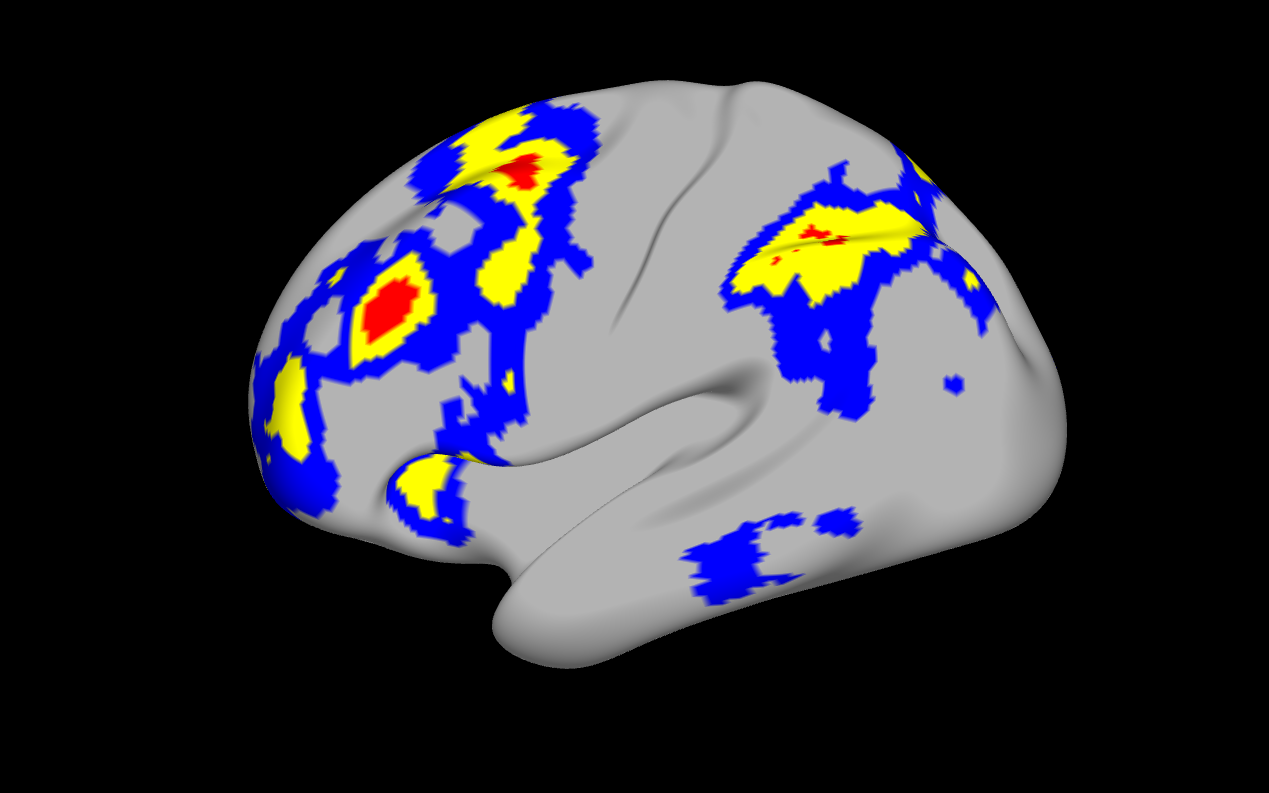

% here, NaN should not be exluded to make sure it is of demension 32492?
srf_cope_display1(hcp_srf.lh,lh_mean-lh_se*4.983,lh_mean+lh_se*4.983, lh_mean, 2)

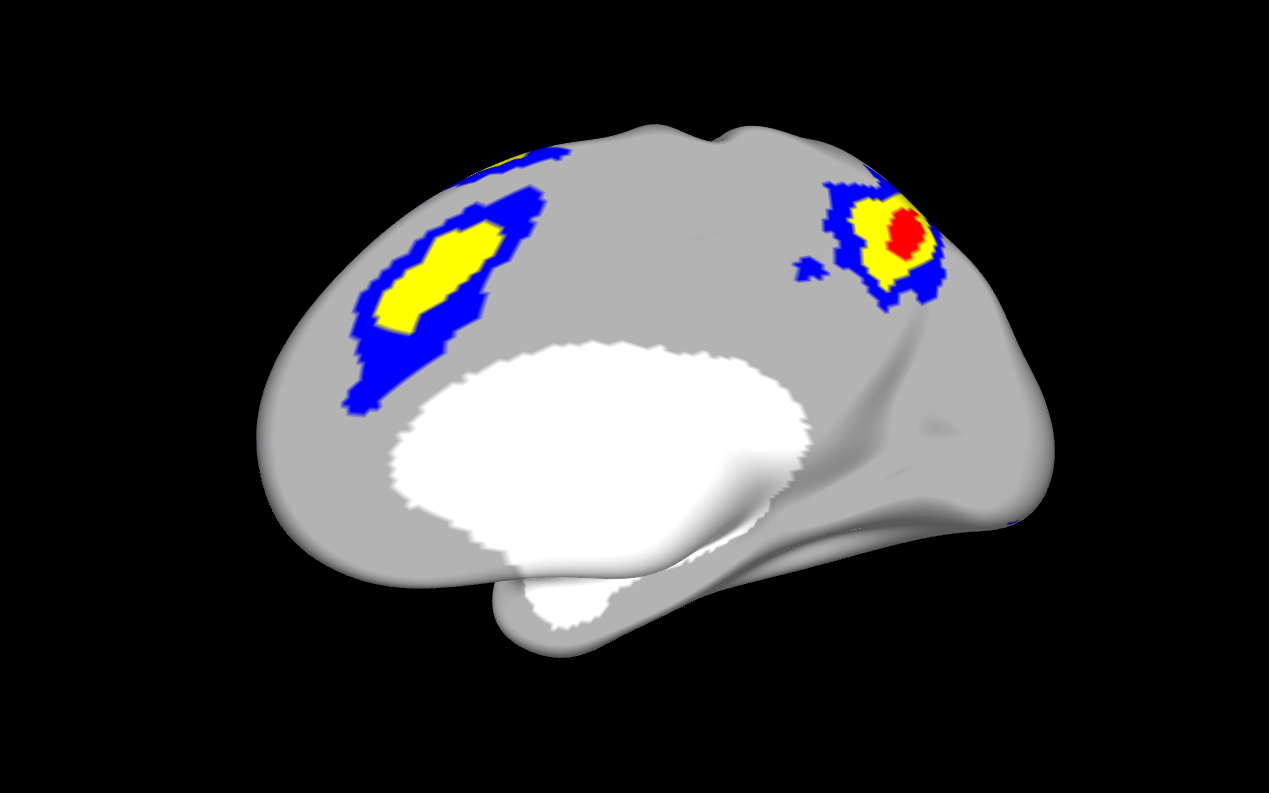

srf_cope_display1(hcp_srf.rh,rh_mean-rh_se*4.949,rh_mean+rh_se*4.949, rh_mean, 2)

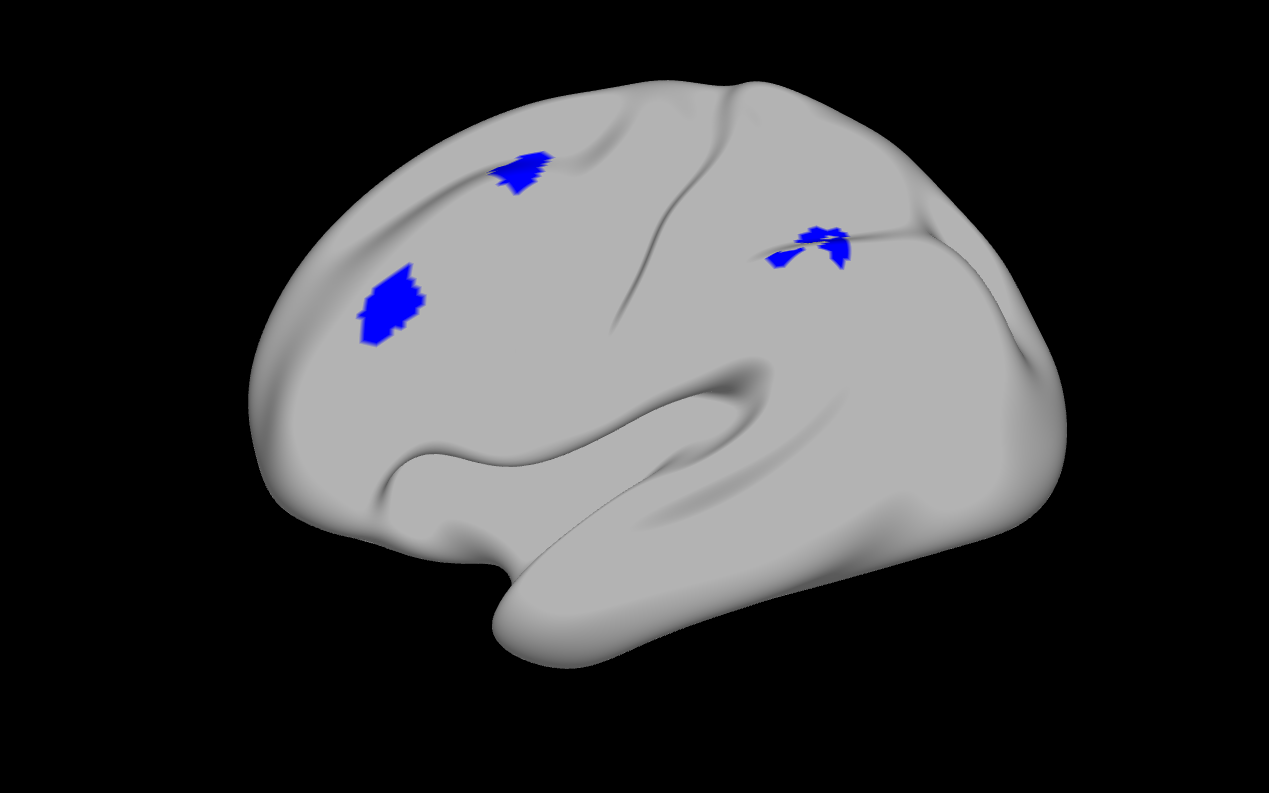

srf_cope_display1(hcp_srf.lh,lh_mean-lh_se*4.983,lh_mean+lh_se*4.983, lh_mean, 5)

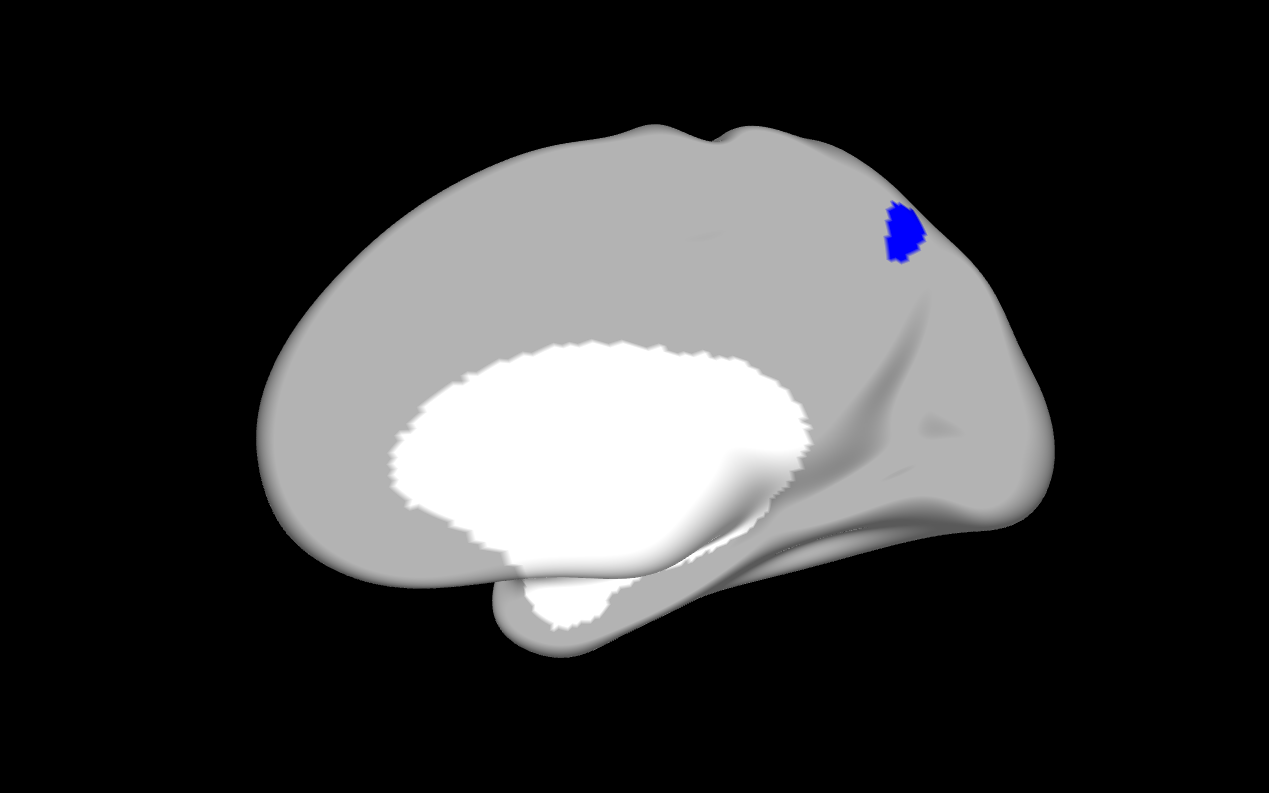

srf_cope_display1(hcp_srf.rh,rh_mean-rh_se*4.949,rh_mean+rh_se*4.949, rh_mean, 5)